# Identify thermal network

## import data

load("identification\I_Ta_Qiron_T.mat");

### time (s)

t = I_Ta_Qiron_T.time;

### current (A)

Iabc = I_Ta_Qiron_T.Iabc;

### ambient temperature (K)

Ta = I_Ta_Qiron_T.Ta;

### iron loss (W)

Qiron = I_Ta_Qiron_T.Qiron;

### temperature (K)

T = I_Ta_Qiron_T.T;

## identification

### create iddata

Ts = 0.01; % sampling period (s)
data = iddata(T,[Iabc,Ta,Qiron],Ts);
data.Tstart = 0;

### model and initial parameters

file = "state_equation_identify";
order = [4,5,4]; % [ydim,udim,xdim]
controller_parameters();
parameters = [
    struct("Name","C123","Unit","","Value",1,"Minimum",0,"Maximum",Inf,"Fixed",false);
    struct("Name","C4","Unit","","Value",1,"Minimum",0,"Maximum",Inf,"Fixed",false);
    struct("Name","R123","Unit","","Value",1,"Minimum",0,"Maximum",Inf,"Fixed",false);
    struct("Name","R456","Unit","","Value",1,"Minimum",0,"Maximum",Inf,"Fixed",false);
    struct("Name","R789","Unit","","Value",1,"Minimum",0,"Maximum",Inf,"Fixed",false);
    struct("Name","R_0","Unit","","Value",R_0_,"Minimum",0,"Maximum",Inf,"Fixed",true);
    struct("Name","T_0","Unit","","Value",T_0_,"Minimum",0,"Maximum",Inf,"Fixed",true);
    struct("Name","alpha","Unit","","Value",alpha_,"Minimum",0,"Maximum",Inf,"Fixed",true);
    struct("Name","ratio_rotor","Unit","","Value",ratio_rotor_,"Minimum",0,"Maximum",Inf,"Fixed",true);
    ];
initial_state = [
    struct("Name","T1","Unit","","Value",T(1,1),"Minimum",-Inf,"Maximum",Inf,"Fixed",true);
    struct("Name","T2","Unit","","Value",T(1,2),"Minimum",-Inf,"Maximum",Inf,"Fixed",true);
    struct("Name","T3","Unit","","Value",T(1,3),"Minimum",-Inf,"Maximum",Inf,"Fixed",true);
    struct("Name","T4","Unit","","Value",T(1,4),"Minimum",-Inf,"Maximum",Inf,"Fixed",true);
    ];
init_sys = idnlgrey(file,order,parameters,initial_state);

### identification with PEM

tic;
sys = pem(data,init_sys);
toc;

経過時間は 74.637335 秒です。


## compare results

### before identification

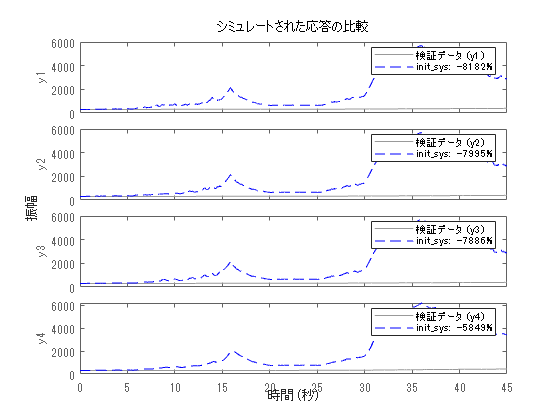

compare(data,init_sys,"--b");

### after identification

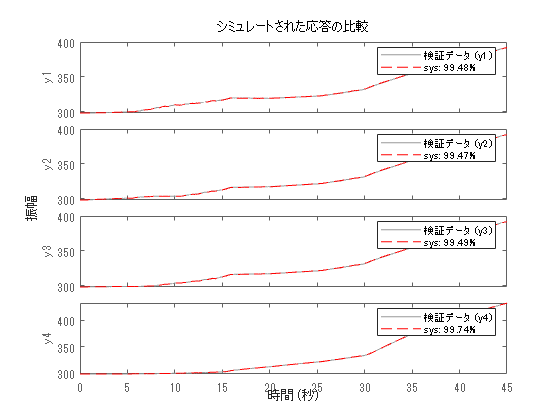

compare(data,sys,"--r");